# Lidar Object Detection Using Complex-YOLO v4 Network

This example shows how to train a Complex-YOLO v4 network to perform object detection on point clouds.

The Complex-YOLO [1] approach is effective for lidar object detection as it directly operates on bird's-eye-view RGB maps that are transformed from the point clouds. In this example, using the Complex-YOLO approach, you train a YOLO v4 [2] network to predict both 2-D box positions and orientation in the bird's-eye-view frame. You then project the 2-D positions along with the orientation predictions back onto the point cloud to generate 3-D bounding boxes around the object of interest.

## **Download Lidar Data Set**

This example uses a subset of the PandaSet data set [3] that contains 2560 preprocessed organized point clouds. Each point cloud covers 360 degrees of view and is specified as a 64-by-1856 matrix. The point clouds are stored in PCD format and their corresponding ground truth data is stored in the `PandaSetLidarGroundTruth.mat` file. The file contains 3-D bounding box information for three classes, which are car, truck, and pedestrian. The size of the data set is 5.2 GB.

Download the PandaSet data set from the given URL using the `helperDownloadPandasetData` helper function, defined at the end of this example.

Stuffs it into outputFolder so we'll do that w/ Explorer.  outputFolder is a confusing name - really should be "workingDir" or something like that.  

Note: the OG code for setting the working directory was: outputFolder = fullfile(tempdir,'Pandaset');  where tempdir was 'C:\Users\art.lompado\AppData\Local\Temp\Pandaset'.  This has 4 subdirectories;  BEVImages, Cuboids, Lidar, and semanticLabels.      

I've created 'C:\Users\art.lompado\Documents\MATLAB\3D Pt Cloud Processing\Initial work - TigerCub Imagery\Kubota ATV\YOLO\WorkingDir' as my working dir and created the same  4 subdirectories within that.  

I think we can make equivalent data(?) for those subdirectories by:

1) I got the Lidar pt. cloud data from my 1'st script and placed it in the Lidar subdirectory 

2) I got the cuboids data (in Cuboids, labeled BEVGroundTruthLabels.mat) from the labeler  

3) I assume I'll get BEV images (BEVImages) from this script (4 sections down) 

4) IDK where to get the files that belong in the semanticLabels subdirectory BUT now that I've been through the whole script, I don't think we ever use them

% outputFolder = fullfile(tempdir,'Pandaset');  %'C:\Users\art.lompado\AppData\Local\Temp\Pandaset'
outputFolder = "C:\Users\art.lompado\Documents\MATLAB\3D Pt Cloud Processing\Initial work - TigerCub Imagery\Kubota ATV\YOLO\WorkingDir";

% Commented this out so don't have to wait to load it again (AL: 02/03/23) 
%lidarURL = ['https://ssd.
% mathworks.com/supportfiles/lidar/data/Pandaset_LidarData.tar.gz'];
%helperDownloadPandasetData(outputFolder,lidarURL);

Depending on your internet connection, the download process can take some time. The code suspends MATLAB® execution until the download process is complete. Alternatively, you can download the data set to your local disk using your web browser and extract the file. If you do so, change the `outputFolder` variable in the code to the location of the downloaded file. The download file contains `Lidar`, `Cuboids`, and `semanticLabels` folders, which contain the point clouds, cuboid label information, and semantic label information respectively. 

## Download Pretrained Model 

This example implements two variants of the complex YOLO v4 object detectors:

- `complex-yolov4-pandaset` —  Standard complex YOLO v4 network trained on bird's-eye-view generated from point clouds of the PandaSet data set

- `tiny-complex-yolov4-pandaset` — Lightweight complex YOLO v4 network trained on bird's-eye-view images generated from point clouds of the PandaSet data set

The pretrained networks are trained on 2 object categories: ATV and pole. 

modelName = 'tiny-complex-yolov4-pandaset';  %Can also choose: 'complex-yolov4-pandaset' 
mdl = downloadPretrainedComplexYOLOv4(modelName);
net = mdl.net; 

## Load Pt. Cloud Data

Create a file datastore to load the PCD files from the specified path using the [`pcread`](docid:vision_ref#buphpf3-1) function.

path = fullfile(outputFolder,'Lidar');
lidarData = fileDatastore(path,'ReadFcn',@(x) pcread(x));
numFiles = length(lidarData.Files);

### Display the full-view point cloud. 

Q: What's the difference between set(ax, 'XLim',[-15 60],...) and xlim([-15 60]); ylim...).  Guide pg. for XLim says "Alternatively, use the [`xlim`](https://www.mathworks.com/help/releases/R2022b/matlab/ref/xlim.html), [`ylim`](https://www.mathworks.com/help/releases/R2022b/matlab/ref/ylim.html), and [`zlim`](https://www.mathworks.com/help/releases/R2022b/matlab/ref/zlim.html) functions to set the limits." so they're basically the same thing right?  In that case, WHY?

NOTE: This displays a single PC every time the loop index is changed.  Leave the axes ranges large!

NOTE: Initial X range = [0, 9141.80].  Initial Y range = [-729.42, 2449.54].

Same problem as the initial script - can't make it a live animation

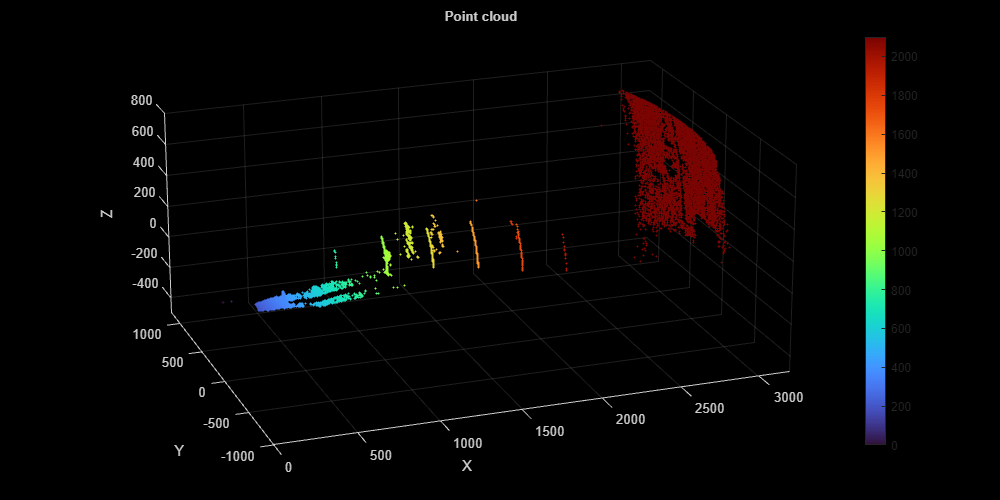

reset(lidarData) % This is here if the lidar datastore needs to be reset

figure
for i = 1:1%25:100
    ptCld = read(lidarData); % doesn't work - the same problem as Preprocess_TigerCub_Data_KubotaATV.mlx
                             
    set(gcf, "Position",[0 0 1000 500]);

    k = pcshow(ptCld.Location, 'MarkerSize', 20, 'Colorsource', "x", AxesVisibility="on"); 

    xlabel("X");ylabel("Y");zlabel("Z"); view(-20, 20);
    xlim([-1 3200]); ylim([-1000,1200]); zlim([-500,800]);  

    title("Point cloud", ["Frame: ", num2str(i)], 'FontSize', 10); % Doesn't work
    colorbar; clim([0, 2100]); colormap(k, "turbo" ); % turbo  jet  parula
    drawnow
end

## This is a WiP - Unfinished

% figure();                        
%                                  
% for i = 1:50:100 %1:nframes 
% 
%     ptCld = read(lidarData); 
% 
%     % Pt size in figure
%     %S = repmat(20, length(frame(i).x), 1);
%     %S = repmat(20, length(ptCld.Location), 1);
%     C = repmat(20, ptCld.Count, 1);
%    
%     ax = gca; % current axes
%     set(gcf, "Position",[0 0 1000 500]);
% 
%     scatter3(ax, ptCld.Location(:,:,1), ptCld.Location(:,:,2), ptCld.Location(:,:,3), 20, ptCld.Location) %, ptCld.Location(:,:), 'filled'
%     xlim([-10, 3200]); ylim([-750, 750]); zlim([-600, 900]); view(10, 20)
%     xlabel('x (Range)'); ylabel('y (Width)'); zlabel('z (Height)')
%     title("Point cloud", ["Frame: ", num2str(i)], 'FontSize', 10);
%  
%     colorbar; clim([0, 3000]); colormap("turbo"); %turbo colorcube
% 
%     daspect([1 1 1]);
%     drawnow
% end

## Load the Ground Truth cuboids

Note:  Obtain the ground truth cuboids from the Lidar Labeler the 1st time by Export(ing) the labeled cuboids to the Workspace (2nd selection under Export).  Save that variable (by default it's named "gTruth") to file and from then on execute the code below.

This should work!  IDK what's wrong.  Our LabelData is only 120x1 and the example's is 2560x3.  Maybe the fact that we only have 1 class makes the call bark?

% gtPath = fullfile(outputFolder,'Cuboids','gTruthCuboidsFromLL.mat');
% data = load(gtPath,'gTruth');  
% Labels = timetable2table(data.LabelData); 
% boxLabels = Labels(:,2:end); % Strip off the time column 

It works if we do it in parts 

Q: What exactly is in this table?  1st col is time (which is stripped off), but what are the rest?  I think the other cols are just the xyz position of the 3 cuboid corners, but it would be good to know for sure 

gtPath = fullfile(outputFolder,'Cuboids','LL_ATV_Cuboids.mat');
LLoutput = load(gtPath);  % Load the output from the LL 

% Now load the part of the structure we want.
data = LLoutput.gTruth; 
Labels = timetable2table(data.LabelData);
boxLabels = Labels(:,2:end)  % Strip off the 1st (time) column

boxLabels = 107×2 table
       ATV            Pole    
    __________    ____________

    1×9 double    {4×9 double}
    1×9 double    {5×9 double}
    1×9 double    {5×9 double}
    1×9 double    {5×9 double}
    1×9 double    {4×9 double}
    1×9 double    {5×9 double}
    1×9 double    {4×9 double}
    1×9 double    {3×9 double}
    1×9 double    {4×9 double}
    1×9 double    {5×9 double}
    1×9 double    {6×9 double}
    1×9 double    {5×9 double}
    1×9 double    {5×9 double}
    1×9 double    {6×9 double}
    1×9 double    {6×9 double}
    1×9 double    {5×9 double}


## Create Bird's-eye-view Image from Point Cloud Data

The PandaSet data consists of full-view point clouds. For this example, crop the full-view point clouds and convert them to a bird's-eye-view images using the standard parameters. These parameters determine the size of the input passed to the network. Selecting a smaller range of point clouds along the x-, y-, and z-axes helps you detect objects that are closer to the origin.

Define the dimensions for the bird's-eye-view image. You can set any dimensions for the bird's-eye-view image but the `preprocessData` helper function (subfunction of transformPCtoBEV_Kubota function) resizes it to network input size. 

Note: Initial X range = [0, 9141.80].  Initial Y range = [-729.42, 2449.54].

xMin = 0;  
xMax = 6000.0;  

yMin = -1000.0;  % MUST be >= 0 which means PC starts at left side of image.  FIXED - see transformPCtoBEV_Kubota.m
yMax = 1000.0;  

zMin = -500.0;  
zMax = 750.0;

For this example, the network input size is 608-by-608.

bevHeight = 608;
bevWidth = 608;

Find the grid resolution.

gridW = (yMax - yMin)/bevWidth;
gridH = (xMax - xMin)/bevHeight;

Define the grid parameters.

gridParams = {{xMin,xMax,yMin,yMax,zMin,zMax},{bevWidth,bevHeight},{gridW,gridH}};

Convert the training data to bird's-eye-view images by using the transformPCtoBEV_PST helper function, attached to this example as a supporting file.

 You can set `writeFiles` to `false` if your training data is already present in the `outputFolder`.

#### *********************************************************************************************************************************************************************

#### I'm suspicious of this section b/c these images do not look like the BEV images in the Lidar Labeler not to mention the example file (the perspective

#### is different). 

#### I'm wondering if we have a coordinate problem -  something to do with the fact that the example's {x,y,z(range)} vs. our {x(range),y,z}. 

********************************************************************************************************************************************************************************

Note: transformPCtoBEV_Kubota() is a modded ver of the OG transformPCtoBEV() to account for our specific pt. cloud structure, boxLabels, and gridParams.  Mods were minimal but could prove significant so BEWARE and visualize liberally b/c the whole script depends on this section output.

writeFiles = true; %false;
if writeFiles
    transformPCtoBEV_Kubota(lidarData,boxLabels,gridParams,outputFolder);
end

## Visualize BEV images

Read in the BEV images created in the last cell & display them.  Note BEV images take the pt. clouds from 3D to 2D

BEVPath = fullfile(outputFolder,'BEVImages');
BEVfiles = dir(strcat(BEVPath,'\*.jpg'));

So these pics do not look like the example script and I'm wondering if we have a coordinate problem.  The example's {x,y,z(range)} = our {x(range),y,z}.  Also the BEV images from the LL are kinda like this except different perspective - see below

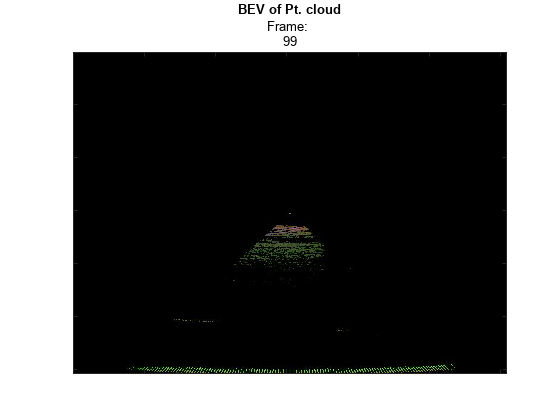

figure()
for i = 1:1:numFiles
    fullfilename = fullfile(BEVPath,BEVfiles(i).name);
    pause(0.05);

    image(imread(fullfilename))

    xticklabels({});yticklabels({});
    title("BEV of Pt. cloud", ["Frame: ", num2str(i)], 'FontSize', 10); 

    drawnow
end

If I just do an "xy view" on the point cloud from above I get the image on the left.  When I use the Lidar Labeler App the BEV gives the image on the right:

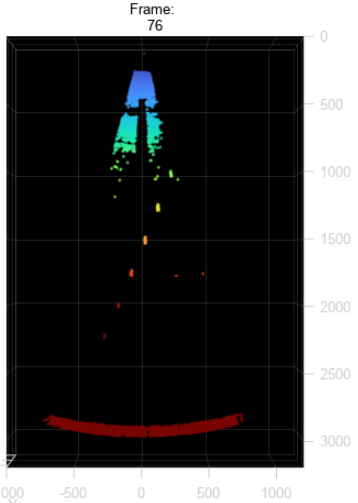    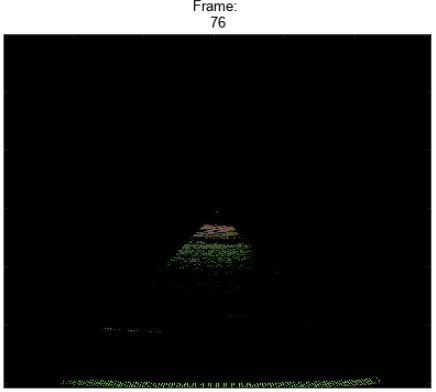    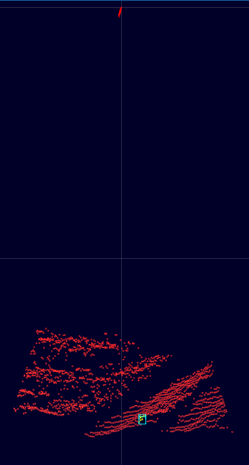

## **Create Datastore Objects for Training**

Create a datastore for loading the bird's-eye-view images.

dataPath = fullfile(outputFolder,'BEVImages');
imds = imageDatastore(dataPath);

Create a datastore for loading the ground truth boxes.

labelPath = fullfile(outputFolder,'Cuboids','BEVGroundTruthLabels.mat');
load(labelPath,'processedLabels');
blds = boxLabelDatastore(processedLabels);

Remove the data that has no labels from the training data.

[imds,blds] = removeEmptyData(imds,blds);
imds

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\Kubota ATV\YOLO\WorkingDir\BEVImages\0001.jpg';
                              ' ...\Kubota ATV\YOLO\WorkingDir\BEVImages\0002.jpg';
                              ' ...\Kubota ATV\YOLO\WorkingDir\BEVImages\0003.jpg'
                               ... and 104 more
                              }
                     Folders: {
                              ' ...\Initial work - TigerCub Imagery\Kubota ATV\YOLO\WorkingDir\BEVImages'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


blds

blds =   boxLabelDatastore with properties:

    LabelData: 
               107x2 cell array
               
               {5×5 double}    {5×1 categorical}
               {6×5 double}    {6×1 categorical}
               {6×5 double}    {6×1 categorical}
               
                ... and 104 more rows
    ReadSize: 1


Split the data set into a training set for training the network and a test set for evaluating the network. Use 60% of the data for training set and the rest for testing..

rng(0);
shuffledIndices = randperm(size(imds.Files,1));
idx = floor(0.6 * length(shuffledIndices));  %Why just 60%?  Typically it's 80%

Split the image datastore into training and test sets.

imdsTrain = subset(imds,shuffledIndices(1:idx));
imdsTest = subset(imds,shuffledIndices(idx+1:end));
[size(imdsTrain.Files),size(imdsTest.Files)]

ans =     64     1    43     1


Split the box label datastore into training and test sets.

bldsTrain = subset(blds,shuffledIndices(1:idx));
bldsTest = subset(blds,shuffledIndices(idx+1:end));
[size(bldsTrain.LabelData),size(bldsTest.LabelData)]

ans =     64     2    43     2


Combine the image and box label datastores.

trainData = combine(imdsTrain,bldsTrain);
testData = combine(imdsTest,bldsTest);

Use the `validateInputDataComplexYOLOv4` helper function, attached to this example as a supporting file, to detect:

- Samples with an invalid image format or that contain NaNs

- Bounding boxes containing zeros, NaNs, Infs, or are empty

- Missing or noncategorical labels.

validateInputDataComplexYOLOv4(trainData);
validateInputDataComplexYOLOv4(testData);

## Preprocess Training Data

Preprocess the training data to prepare for training. The `preprocessData` helper function, listed at the end of the example, applies the following operations to the input data.

- Resize the images to the network input size.

- Scale the image pixels in the range [0 1].                  

- Set `isRotRect` to `true` to return the rotated rectangles. 

networkInputSize = [608 608 3];
isRotRect = true; %Do we want to do this??
preprocessedTrainingData = transform(trainData,@(data)preprocessData(data,networkInputSize,isRotRect));

Read the preprocessed training data.

data = read(preprocessedTrainingData);

Display an image with the bounding boxes.

Q: So what frame is this?  I thought frame 1 but it looks like the final frame

I = data{1,1};
bbox = data{1,2};
labels = data{1,3};

 ****************************************************************************************************************************************************

 Had to update this next function to handle our classes (ATV, poles) as opposed to the OG code which did (Car, Truck, Pedestrian)

****************************************************************************************************************************************************

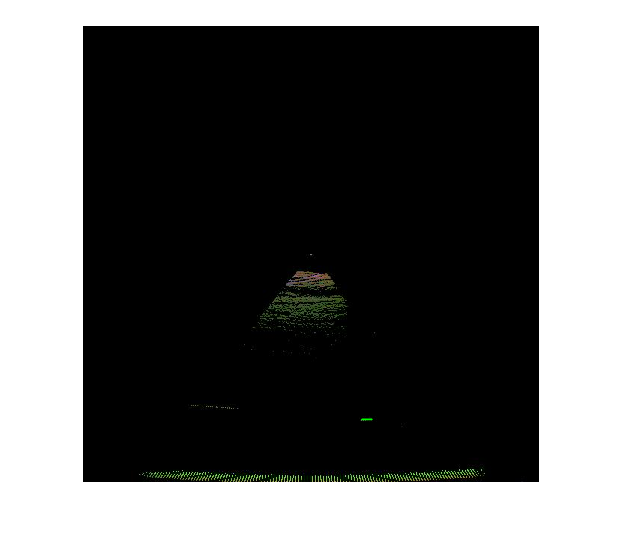

%helperDisplayBoxes(I,bbox,labels);
helperDisplayBoxes_ATV(I,bbox,labels);  

% Q: So what frame is this showing?  Ans: Frame 99. It's the 1st of the training imgs, which changes every time we run it (right?)

Reset the datastore to the state where no data has been read from it.  Resetting allows re-reading from the same datastore.

reset(preprocessedTrainingData);

## Modify Pretrained Complex-YOLO V4 Network

The Complex-YOLO V4 network uses anchor boxes estimated from the training data to have better initial estimate corresponding to the type of data set and to help the network learn to predict the boxes accurately.

First, because the training images vary in size, use the [`transform`](docid:matlab_ref#mw_16489124-fe7e-4381-b715-8d3b8b30a9f6) function to preprocess the training data and resize all the images to the same size.

Specify the number of anchors:

- `complex-yolov4-pandaset model` —  Specify 9 anchors

- `tiny-complex-yolov4-pandaset model` —  Specify 6 anchors

For reproducibility, set the random seed. Estimate the anchor boxes using `estimateAnchorBoxes` function. You can set `isRotRect` to false because the rotation angle is not necessary for the bounding boxes to estimate the anchors. For more information about anchor boxes, refer to "Specify Anchor Boxes" section of [Getting Started with YOLO v4](docid:vision_ug#mw_09b91dd4-f3cc-44fc-a420-ef5b7b940cb4).  

WARNING: Present output for anchorBoxes is a 6x2 array but in the example it's a 2x1 Cell Array with the 1st and 2nd entries being 6x1 arrays.

                   DKW estimateAnchorBoxes() produces 2 different outputs although I suspect it has to do w/ the fact that we only have 1 class(???)

rng(0)
isRotRect = false;
trainingDataForEstimation = transform(trainData,@(data)preprocessData(data,networkInputSize,isRotRect));
numAnchors = 6;
[anchorBoxes,meanIoU] = estimateAnchorBoxes(trainingDataForEstimation,numAnchors)

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 8).


anchorBoxes =      5     4
     1    17
     3     9
     6     7
     5    16
     6    12


meanIoU = 0.7858

Configure the pretrained model for training using the `configureComplexYOLOV4` function. This function configures the detection head of the YOLO v4 model to predict the angle regression along with bounding boxes, the objectness score, and classification scores. 

This function returns a the modified layer graph, network output names, reordered anchor boxes, and anchor box masks to select anchor boxes to use in the detected heads. The size of an anchor box assigned to a detection head corresponds to the size of the feature map output from the detection head. The function reorders the anchor boxes in such a way that the large anchor boxes are assigned to the feature maps with low resolution and small anchor boxes to the feature maps with high resolution.

% Specify the class names to use for training.
% classNames = {'Car'
%               'Truck'
%               'Pedestrain'};
% [net,networkOutputs,anchorBoxes] = configureComplexYOLOv4(net,classNames,anchorBoxes,modelName);

classNames = {'ATV'
              'Pole'};
[~,networkOutputs,~] = configureComplexYOLOv4(net,classNames,anchorBoxes,modelName);

'net' requires Statistics and Machine Learning Toolbox.

## Specify Training Options

Specify these training options.

Q: What do these options actually mean? (AL: 02/10/23)

- Set the number of epochs to 90.   Why? (AL: 02/10/23)

- Set the mini batch size to 8. Stable training is possible with higher learning rates when higher mini batch size is used. Set this value depending on the memory available.   See comment in next cell (AL: 02/10/23)

- Set the learning rate to 0.001.   Why? (AL: 02/10/23)

- Set the warmup period to 1000 iterations. It helps in stabilizing the gradients at higher learning rates. 

- Set the L2 regularization factor to 0.001.   Why? (AL: 02/10/23)

- Specify the penalty threshold as 0.5. Detections that overlap less than 0.5 with the ground truth are penalized.   Why? (AL: 02/10/23)

- Initialize the velocity of the gradient as [ ], which is used by SGDM to store the velocity of the gradients.

maxEpochs =  90;    % When we train on this Example data the max epoch is 22.  Don't know why it's set to 90.
miniBatchSize = 8;  % This was 8. Default for minibatchqueue() function is 128 but only can do 16 w/ the Example
                    % data, otherwise graphics card runs out of memory. In this case, takes about 10-11s per epoch  
                    
learningRate = 0.001;
warmupPeriod = 1000;
l2Regularization = 0.001;
penaltyThreshold = 0.5;
velocity = [];

## Train Model

Train on a GPU, if one is available. Using a GPU requires Parallel Computing Toolbox™ and a CUDA® enabled NVIDIA® GPU. For information on supported devices, see [GPU Support by Release](docid:distcomp_ug#mw_57e04559-0b60-42d5-ad55-e77ec5f5865f).

Use the `minibatchqueue` function to split the preprocessed training data into batches with the supporting function `createBatchData`, defined at the end of the example, which returns the batched images and bounding boxes combined with the respective class IDs. For faster extraction of the batch data for training, set the `dispatchInBackground` to `true` to use a parallel pool.

`minibatchqueue` automatically detects whether a GPU is available. If you do not have a GPU or do not want to use one for training, set the `OutputEnvironment` parameter to `cpu`. 

Q: Where is the `OutputEnvironment parameter they speak of? ` (AL: 02/10/23)

`   Ans: It's in the minibatchqueue() call. They don't explicitly set it here - look at the Help for minibatchqueue. ` 

if canUseParallelPool
   dispatchInBackground = true;  % Detected GPUs on my work machine so that's good (AL: 02/10/23) 
else
   dispatchInBackground = false;
end

% minibatchqueue() creates mini-batches for deep learning
mbqTrain = minibatchqueue(preprocessedTrainingData,2, ...
        "MiniBatchSize",miniBatchSize,...
        "MiniBatchFcn",@(images,boxes,labels) createBatchData(images,boxes,labels,classNames), ...
        "MiniBatchFormat",["SSCB",""],...
        "DispatchInBackground",dispatchInBackground,...
        "OutputCast",["","double"]);

## Train Model - cont.

Create the training progress plot using the supporting function `configureTrainingProgressPlotter.`

Finally, specify the custom training loop. For each iteration:

- Read data from the `minibatchqueue`. If it has no more data, reset the `minibatchqueue` and shuffle.

- Evaluate the model gradients using the `dlfeval` and the `modelGradients` supporting function, listed at the end of this example.

- Apply a weight decay factor to the gradients to regularization for more robust training.bevHeight

- Determine the learning rate based on the iterations using the `piecewiseLearningRateWithWarmup` supporting function.

- Update the `net` parameters using the `sgdmupdate` function.

- Update the `state` parameters of net with the moving average.

- Display the learning rate, total loss, and the individual losses (box loss, object loss, and class loss) for every iteration. Use these values to interpret how the respective losses change in each iteration. For example, a sudden spike in the box loss after a few iterations implies that the predictions contain Inf values or NaNs.

- Update the training progress plot.

You can terminate the training if the loss saturates for a few epochs.

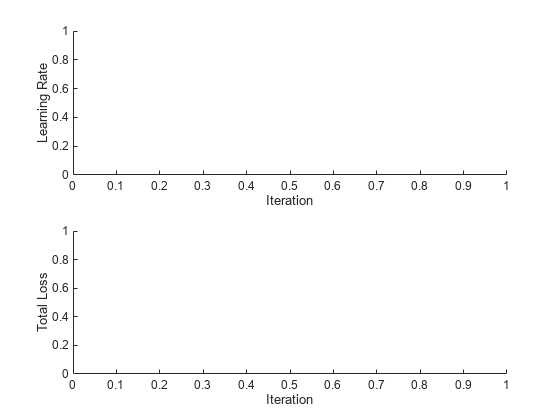

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 8).


Brace indexing is not supported for variables of this type.

Error in complexYOLOv4Forward>extractPredictions (line 44)
    numAnchors = size(anchorBoxes{ii},1);

Error in complexYOLOv4Forward (

doTraining = true; %true; false

if doTraining
    iteration = 0;
   
    % Create subplots for the learning rate and mini-batch loss.
    fig = figure;
    [lossPlotter, learningRatePlotter] = configureTrainingProgressPlotter(fig);

    tic
    % Custom training loop.
    for epoch = 1:maxEpochs
          
        reset(mbqTrain);
        shuffle(mbqTrain);
        
        while(hasdata(mbqTrain))
            iteration = iteration + 1;
           
            [XTrain,YTrain] = next(mbqTrain);
            
            % Evaluate the model gradients and loss using dlfeval and the
            % modelGradients function.
            [gradients,state,lossInfo] = dlfeval(@modelGradients,net,XTrain,YTrain,anchorBoxes,penaltyThreshold,networkOutputs);
    
            % Apply L2 regularization.
            gradients = dlupdate(@(g,w) g + l2Regularization*w, gradients, net.Learnables);
    
            % Determine the current learning rate value.
            currentLR = piecewiseLearningRateWithWarmup(iteration,epoch,learningRate,warmupPeriod,maxEpochs);
            
            % Update the network learnable parameters using the SGDM optimizer.
            [net,velocity] = sgdmupdate(net,gradients,velocity,currentLR);
    
            % Update the state parameters of dlnetwork.
            net.State = state;
            
            % Display progress.
            if mod(iteration,10)==1
                displayLossInfo(epoch,iteration,currentLR,lossInfo);
            end
                
            % Update training plot with new points.
            updatePlots(lossPlotter,learningRatePlotter,iteration,currentLR,lossInfo.totalLoss);
        end
    end
    toc
else
    net = mdl.net;
    anchorBoxes = mdl.anchorBoxes;
end

To find optimal training options by sweeping through ranges of hyperparameter values, use the [Experiment Manager](docid:nnet_ref#mw_301a3a9d-998a-4668-aec4-f94646b76921) app.

## Evaluate Model

Computer Vision Toolbox™ provides object detector evaluation functions to measure common metrics such as average precision (`evaluateDetectionAOS`) for rotated rectangles. This example uses the average orientation similarity (AOS) metric. AOS is a metric for measuring detector performance on rotated rectangle detections. This metric provides a single number that incorporates the ability of the detector to make correct classifications (precision) and the ability of the detector to find all relevant objects (recall).

% Create a table to hold the bounding boxes, scores, and labels returned by
% the detector. 
results = table('Size',[0 3], ...
    'VariableTypes',{'cell','cell','cell'}, ...
    'VariableNames',{'Boxes','Scores','Labels'});

% Run the detector on images in the test set and collect the results.
reset(testData)
while hasdata(testData)
    % Read the datastore and get the image.
    data = read(testData);
    image = data{1,1};
    
    % Run the detector.
    executionEnvironment = 'auto';
    [bboxes,scores,labels] = detectComplexYOLOv4(net,image,anchorBoxes,classNames,executionEnvironment);
    
    % Collect the results.
    tbl = table({bboxes},{scores},{labels},'VariableNames',{'Boxes','Scores','Labels'});
    results = [results; tbl];
end

Brace indexing is not supported for variables of this type.

Error in cell2mat (line 42)
cellclass = class(c{1});

Error in detectComplexYOLOv4>postprocess (line 57)
anchorBoxesSet = cell2mat(anchorBoxes);

Error in 


% Evaluate the object detector using the average precision metric.
metrics = evaluateDetectionAOS(results, testData)

## Detect Objects Using Trained Complex-YOLO V4

Use the network for object detection.

% Read the datastore.
reset(testData)
data = read(testData);

% Get the image.
I = data{1,1};

% Run the detector.
executionEnvironment = 'auto';
[bboxes,scores,labels] = detectComplexYOLOv4(net,I,anchorBoxes,classNames,executionEnvironment);

Brace indexing is not supported for variables of this type.

Error in cell2mat (line 42)
cellclass = class(c{1});

Error in detectComplexYOLOv4>postprocess (line 57)
anchorBoxesSet = cell2mat(anchorBoxes);

Error in 


% Display the output.
figure
helperDisplayBoxes(I,bboxes,labels);

Transfer the detected boxes to a point cloud using the `transferbboxToPointCloud` helper function, attached to this example as a supporting file.

lidarTestData = subset(lidarData,shuffledIndices(idx+1:end));
ptCld = read(lidarTestData);
[ptCldOut,bboxCuboid] = transferbboxToPointCloud(bboxes,gridParams,ptCld);
helperDisplayBoxes(ptCldOut,bboxCuboid,labels);

## Supporting Functions

### Model Gradients

The function `modelGradients` takes as input the Complex-YOLO v4 network, a mini-batch of input data `XTrain` with corresponding ground truth boxes `YTrain`, and the specified penalty threshold. It returns the gradients of the loss with respect to the learnable parameters in `net`, the corresponding mini-batch loss information, and the state of the current batch.

The `modelGradients` function computes the total loss and gradients by performing these operations.

- Generate predictions from the input batch of images using the `complexYOLOv4Forward` method.

- Collect predictions on the CPU for postprocessing.

- Convert the predictions from the Complex-YOLO v4 grid cell coordinates to bounding box coordinates to allow easy comparison with the ground truth data.

- Generate targets for loss computation by using the converted predictions and ground truth data. Generate the targets for bounding box positions (x, y, width, height, yaw), object confidence, and class probabilities. See the supporting function `generateComplexYOLOv4Targets`.

- Calculate the mean squared error of the predicted bounding box coordinates with target boxes using the supporting function `bboxOffsetLoss`, defined at the end of the example.

- Calculate the binary cross-entropy of the predicted object confidence score with a target object confidence score using the supporting function `objectnessLoss`, defined at the end of the example.

- Calculate the binary cross-entropy of the predicted class of object with the target using the supporting function `classConfidenceLoss`, defined at the end of the example.

- Compute the total loss as the sum of all losses.

- Compute the gradients of learnables with respect to the total loss.

function [gradients,state,info] = modelGradients(net,XTrain,YTrain,anchors,penaltyThreshold,networkOutputs)

    inputImageSize = size(XTrain,1:2);
    
    % Gather the ground truths in the CPU for postprocessing.
    YTrain = gather(extractdata(YTrain));
    
    % Extract the predictions from the network.
    [YPredCell,state] = complexYOLOv4Forward(net,XTrain,networkOutputs,anchors);
    
    % Gather the activations in the CPU for postprocessing and extract dlarray data. 
    gatheredPredictions = cellfun(@ gather,YPredCell(:,1:8),'UniformOutput',false); 
    gatheredPredictions = cellfun(@ extractdata, gatheredPredictions,'UniformOutput', false);
    
    % Convert predictions from grid cell coordinates to box coordinates.
    tiledAnchors = generateTiledAnchorsComplexYolov4(gatheredPredictions(:,2:5),anchors);
    gatheredPredictions(:,2:5) = applyAnchorBoxOffsetsComplexYolov4(tiledAnchors,gatheredPredictions(:,2:5),inputImageSize);
    
    % Generate targets for predictions from the ground truth data.
    [boxTarget,objectnessTarget,classTarget,objectMaskTarget,boxErrorScale] = generateComplexYOLOv4Targets(gatheredPredictions,YTrain,inputImageSize,anchors,penaltyThreshold);
    
    % Compute the loss.
    boxLoss = bboxOffsetLoss(YPredCell(:,[2 3 9 10 6 7]),boxTarget,objectMaskTarget,boxErrorScale);
    objLoss = objectnessLoss(YPredCell(:,1),objectnessTarget,objectMaskTarget);
    clsLoss = classConfidenceLoss(YPredCell(:,8),classTarget,objectMaskTarget);
    totalLoss = boxLoss + objLoss + clsLoss;
    
    info.boxLoss = boxLoss;
    info.objLoss = objLoss;
    info.clsLoss = clsLoss;
    info.totalLoss = totalLoss;
    
    % Compute the gradients of learnables with regard to the loss.
    gradients = dlgradient(totalLoss,net.Learnables);
end

### Loss Functions

Compute the mean squared error for the bounding box position.

function boxLoss = bboxOffsetLoss(boxPredCell,boxDeltaTarget,boxMaskTarget,boxErrorScaleTarget)
    lossX = sum(cellfun(@(a,b,c,d) mse(a.*c.*d,b.*c.*d),boxPredCell(:,1),boxDeltaTarget(:,1),boxMaskTarget(:,1),boxErrorScaleTarget));
    lossY = sum(cellfun(@(a,b,c,d) mse(a.*c.*d,b.*c.*d),boxPredCell(:,2),boxDeltaTarget(:,2),boxMaskTarget(:,1),boxErrorScaleTarget));
    lossW = sum(cellfun(@(a,b,c,d) mse(a.*c.*d,b.*c.*d),boxPredCell(:,3),boxDeltaTarget(:,3),boxMaskTarget(:,1),boxErrorScaleTarget));
    lossH = sum(cellfun(@(a,b,c,d) mse(a.*c.*d,b.*c.*d),boxPredCell(:,4),boxDeltaTarget(:,4),boxMaskTarget(:,1),boxErrorScaleTarget));
    
    lossYaw1 = sum(cellfun(@(a,b,c,d) mse(a.*c.*d,b.*c.*d),boxPredCell(:,5),boxDeltaTarget(:,5),boxMaskTarget(:,1),boxErrorScaleTarget));
    lossYaw2 = sum(cellfun(@(a,b,c,d) mse(a.*c.*d,b.*c.*d),boxPredCell(:,6),boxDeltaTarget(:,6),boxMaskTarget(:,1),boxErrorScaleTarget));
    
    boxLoss = lossX+lossY+lossW+lossH+lossYaw1+lossYaw2;
end

Compute the binary cross-entropy loss for the class confidence score.

function clsLoss = classConfidenceLoss(classPredCell,classTarget,boxMaskTarget)
    clsLoss = sum(cellfun(@(a,b,c) crossentropy(a.*c,b.*c,'TargetCategories','independent'),classPredCell,classTarget,boxMaskTarget(:,3)));
end

Compute the binary cross-entropy loss for the objectness score.

function objLoss = objectnessLoss(objectnessPredCell,objectnessDeltaTarget,boxMaskTarget)
    objLoss = sum(cellfun(@(a,b,c) crossentropy(a.*c,b.*c,'TargetCategories','independent'),objectnessPredCell,objectnessDeltaTarget,boxMaskTarget(:,2)));
end

### Preprocess Data

function data = preprocessData(data,targetSize,isRotRect)
% Resize the images and scale the pixels to between 0 and 1. Also scale the
% corresponding bounding boxes.
for ii = 1:size(data,1)
    I = data{ii,1};
    imgSize = size(I);
    
    % Convert an input image with a single channel to three channels.
    if numel(imgSize) < 3 
        I = repmat(I,1,1,3);
    end
    bboxes = data{ii,2};

    I = im2single(imresize(I,targetSize(1:2)));
    scale = targetSize(1:2)./imgSize(1:2);
    bboxes = bboxresize(bboxes,scale);

    if ~isRotRect
        bboxes = bboxes(:,1:4);
    end
    
    data(ii, 1:2) = {I,bboxes};
end
end

function [XTrain,YTrain] = createBatchData(data,groundTruthBoxes,groundTruthClasses,classNames)
% Return images combined along the batch dimension in XTrain and
% normalized bounding boxes concatenated with classIDs in YTrain.

    % Concatenate images along the batch dimension.
    XTrain = cat(4,data{:,1});
    
    % Get class IDs from the class names.
    classNames = repmat({categorical(classNames')},size(groundTruthClasses));
    [~,classIndices] = cellfun(@(a,b)ismember(a,b),groundTruthClasses,classNames,'UniformOutput',false);
    
    % Append the label indexes and training image size to scaled bounding boxes
    % and create a single cell array of responses.
    combinedResponses = cellfun(@(bbox,classid)[bbox,classid],groundTruthBoxes,classIndices,'UniformOutput',false);
    len = max(cellfun(@(x)size(x,1),combinedResponses));
    paddedBBoxes = cellfun(@(v) padarray(v,[len-size(v,1),0],0,'post'),combinedResponses,'UniformOutput',false);
    YTrain = cat(4,paddedBBoxes{:,1});
end

### Learning Rate Schedule Function

function currentLR = piecewiseLearningRateWithWarmup(iteration,epoch,learningRate,warmupPeriod,numEpochs)
% The piecewiseLearningRateWithWarmup function computes the current
% learning rate based on the iteration number.
    persistent warmUpEpoch;
    
    if iteration <= warmupPeriod
        % Increase the learning rate for the number of iterations in the warmup period.
        currentLR = learningRate*((iteration/warmupPeriod)^4);
        warmUpEpoch = epoch;
    elseif iteration >= warmupPeriod && epoch < warmUpEpoch+floor(0.6*(numEpochs-warmUpEpoch))
        % After the warmup period, keep the learning rate constant if the remaining number of epochs is less than 60 percent. 
        currentLR = learningRate;
        
    elseif epoch >= warmUpEpoch + floor(0.6*(numEpochs-warmUpEpoch)) && epoch < warmUpEpoch+floor(0.9*(numEpochs-warmUpEpoch))
        % If the remaining number of epochs is more than 60 percent but less
        % than 90 percent, multiply the learning rate by 0.1.
        currentLR = learningRate*0.1;
        
    else
        % If more than 90 percent of the epochs remain, multiply the learning
        % rate by 0.01.
        currentLR = learningRate*0.01;
    end
end

### **Utility Functions**

function [lossPlotter,learningRatePlotter] = configureTrainingProgressPlotter(f)
% Create the subplots to display the loss and learning rate.

    figure(f);
    clf
    subplot(2,1,1);
    ylabel('Learning Rate');
    xlabel('Iteration');
    learningRatePlotter = animatedline;
    subplot(2,1,2);
    ylabel('Total Loss');
    xlabel('Iteration');
    lossPlotter = animatedline;
end

function displayLossInfo(epoch,iteration,currentLR,lossInfo)
% Display loss information for each iteration.
    disp("Epoch : " + epoch + " | Iteration : " + iteration + " | Learning Rate : " + currentLR + ...
       " | Total Loss : " + double(gather(extractdata(lossInfo.totalLoss))) + ...
       " | Box Loss : " + double(gather(extractdata(lossInfo.boxLoss))) + ...
       " | Object Loss : " + double(gather(extractdata(lossInfo.objLoss))) + ...
       " | Class Loss : " + double(gather(extractdata(lossInfo.clsLoss))));
end

function updatePlots(lossPlotter,learningRatePlotter,iteration,currentLR,totalLoss)
% Update loss and learning rate plots.
    addpoints(lossPlotter,iteration,double(extractdata(gather(totalLoss))));
    addpoints(learningRatePlotter,iteration,currentLR);
    drawnow
end

% ***************************
% Remmed out & updated below
% ***************************

% function helperDisplayBoxes(obj,bboxes,labels)
% % Display the boxes over the image and point cloud.
%     figure
%     if ~isa(obj,'pointCloud')
%         imshow(obj)
%         shape = 'rectangle';
%     else
%         pcshow(obj.Location);
%         shape = 'cuboid';
%     end
%     showShape(shape,bboxes(labels=='Car',:),...
%                   'Color','green','LineWidth',0.5);hold on;
%     showShape(shape,bboxes(labels=='Truck',:),...
%               'Color','magenta','LineWidth',0.5);
%     showShape(shape,bboxes(labels=='Pedestrain',:),...
%               'Color','yellow','LineWidth',0.5);
%     hold off;
% end

function helperDisplayBoxes_ATV(obj,bboxes,labels)
% Display the boxes over the image and point cloud.
    figure
    if ~isa(obj,'pointCloud')
        imshow(obj,'InitialMagnification',75) % show image at 75%
        shape = 'rectangle';
    else
        pcshow(obj.Location);
        shape = 'cuboid';
    end
    showShape(shape,bboxes(labels=='ATV',:),...
                  'Color','green','LineWidth',0.5);hold on;
    showShape(shape,bboxes(labels=='Pole',:),...
              'Color','magenta','LineWidth',0.5);
    hold off;
end

function helperDownloadPandasetData(outputFolder,lidarURL)
% Download the data set from the given URL to the output folder.
    lidarDataTarFile = fullfile(outputFolder,'Pandaset_LidarData.tar.gz');    
    if ~exist(lidarDataTarFile,'file')
        mkdir(outputFolder);        
        disp('Downloading PandaSet Lidar driving data (5.2 GB)...');
        websave(lidarDataTarFile,lidarURL);
        untar(lidarDataTarFile,outputFolder);
    end    
    % Extract the file.
    if (~exist(fullfile(outputFolder,'Lidar'),'dir'))...
            &&(~exist(fullfile(outputFolder,'Cuboids'),'dir'))
        untar(lidarDataTarFile,outputFolder);
    end
end

## References

[1] Simon, Martin, Stefan Milz, Karl Amende, and Horst-Michael Gross. "Complex-YOLO: Real-Time 3D Object Detection on Point Clouds". *ArXiv:1803.06199 [Cs]*, 24 September 2018. [https://arxiv.org/abs/1803.06199](http://arxiv.org/abs/1803.06199).

[2] Bochkovskiy, Alexey, Chien-Yao Wang, and Hong-Yuan Mark Liao. "YOLOv4: Optimal Speed and Accuracy of Object Detection". *ArXiv:2004.10934 [Cs, Eess]*, 22 April 2020. [https://arxiv.org/abs/2004.10934](http://arxiv.org/abs/2004.10934).

[3] [PandaSet](https://scale.com/open-datasets/pandaset) is provided by Hesai and Scale under the [CC-BY-4.0 license](https://creativecommons.org/licenses/by/4.0).

*Copyright 2022 The MathWorks, Inc.*